% LQG Method

% considering 12 state variables for the system 
% The first 6 are actual variables and the other 6 are estimated variables
% which are used to compute the error between the estimated state and true
% state.

% State variables  = [x x_dot theta1 theta1_dot theta2 theta2_dot Estimated_variables] 

% Initial conditions 
X_i = [0, 0, 10, 0, 15, 0, 0, 0, 0, 0, 0, 0];

% computing the gain matrix using the lqr controller function
K_matrix =lqr(A,B,Q,R);

% Process noise term
U_d = diag([0.6, 0.6, 0.6, 0.6, 0.6, 0.6]);
% Measurement noise term
V_t = 1; 

% choosing the desired smallest output vector out of the observable output
% vectors
% Gain matrix for Kalman Filter for output vector x(t)
K_filter = lqr(A', C_01', U_d, V_t)';  

% Initial and step response for the linearsystem_1
disp("Linear System 1")

Linear System 1


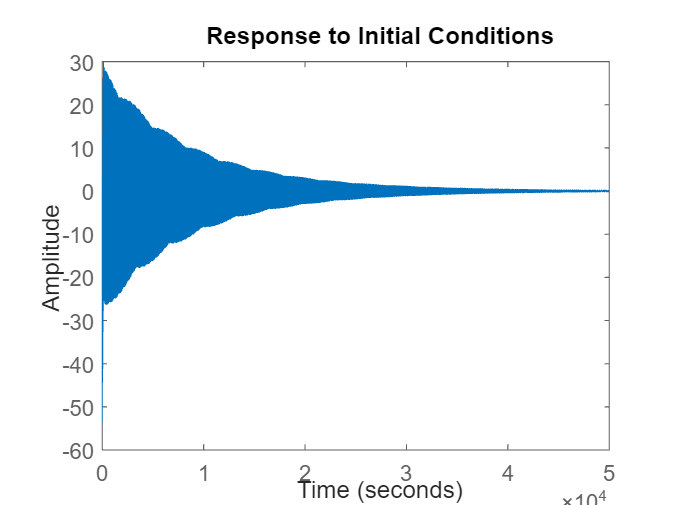

linearSystem_1 = ss([(A-B*K_matrix) B*K_matrix; zeros(size(A)) (A-K_filter*C_01)], [B;zeros(size(B))],[C_01 zeros(size(C_01))], D);
figure
initial(linearSystem_1,X_i)

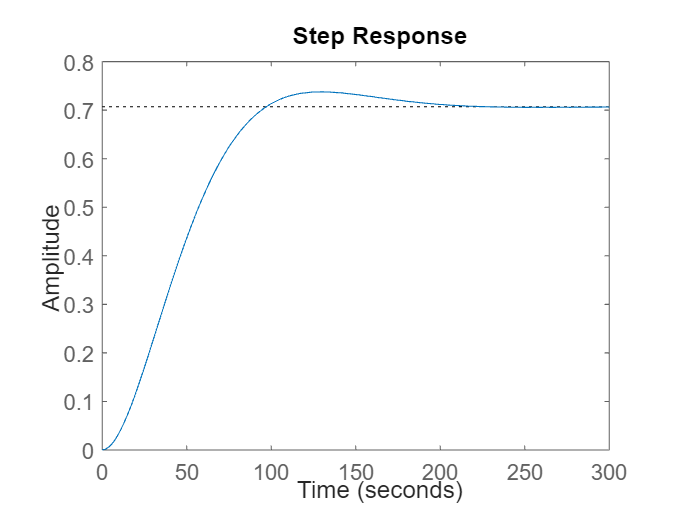

figure
step(linearSystem_1)



% non-linear system control using LQG
disp("LQG non-linear control")

LQG non-linear control


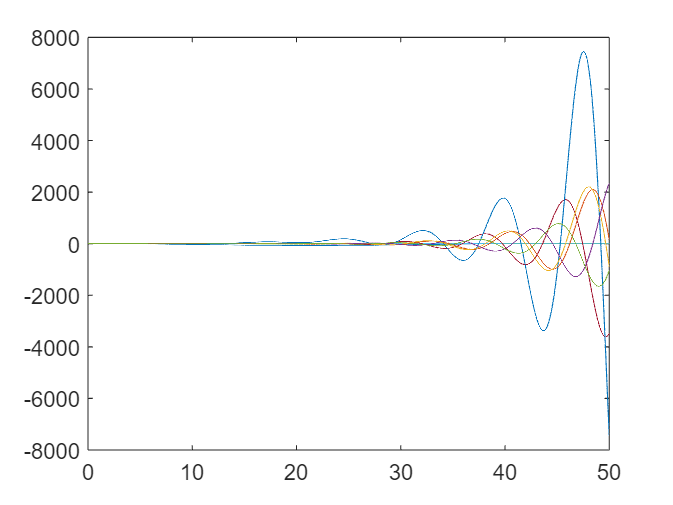

X_i = [0, 0, 10, 0, 15, 0, 0, 0, 0, 0, 0, 0];
Timespan = 0:0.01:50;
[T1,X1] = ode45(@LQG_controller,Timespan,X_i);
plot(T1,X1)

function X_dot = LQG_controller(T1,X)
% Given Initial conditions
% Mass of the Crane, mass of load1, mass of load2, Cable length 1,
% Cable length 2, gravity
M= 1000;
m1= 100; 
m2= 100;
l1= 20; 
l2= 10;
g= 9.81;

% A matrix
A=[0 1 0 0 0 0;
0 0 -(m1*g)/M 0 -(m2*g)/M 0;
0 0 0 1 0 0;
0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
0 0 0 0 0 1;
0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

% B matrix
B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

% Choosing the values for Q and R for estimating the cost function
Q = diag([1, 1, 1, 1, 1, 1]);
R = 0.5;

% Choosing the smallest output vector from the observable output vector
C_01 = [1 0 0 0 0 0]; 

% D 
D = 0; 

[K_matrix] = lqr(A,B,Q,R);
F = - K_matrix*X(1:6);

% Process noise term
U_d = diag([0.6, 0.6, 0.6, 0.6, 0.6, 0.6]);
% Measurement noise term
V_t=1; 
% Gain matrix for Kalman Filter for C1
K_filter =lqr(A', C_01', U_d, V_t)';
% Standard Deviation considering the output vector x(t)
Standard_Deviation = (A-K_filter*C_01)*X(7:12);
X_dot = zeros(12,1);

% X(1) = x
X_dot(1) = X(2); % X_Dot

% X(2) = x_dot
X_dot(2) = (F-(g/2)*(m1*sind(2*X(3))+m2*sind(2*X(5)))-(m1*l1*(X(4)^2)*sind(X(3)))-(m2*l2*(X(6)^2)*sind(X(5))))/(M+m1*((sind(X(3)))^2)+m2*((sind(X(5)))^2)); % X_Doubledot

% X(3) = Theta_1
X_dot(3) = X(4); % Theta_1 dot

% X(4) = Theta_1 dot
X_dot(4) = (X_dot(2)*cosd(X(3))-g*(sind(X(3))))/l1'; % Theta_1 Doubledot;

% X(5)= Theta_2
X_dot(5) = X(6); % Theta_2 Dot

% X(6)= Theta_2 dot;
X_dot(6) = (X_dot(2)*cosd(X(5))-g*(sind(X(5))))/l2; % Theta_2 Doubledot;

% X(7), X(8), X(9), X(10), X(11), X(12)
X_dot(7) = X(2)-X(10);
X_dot(8) = X_dot(2)-Standard_Deviation(2);
X_dot(9) = X(4)-X(11);
X_dot(10) = X_dot(4)-Standard_Deviation(4);
X_dot(11) = X(6)-X(12);
X_dot(12) = X_dot(6)-Standard_Deviation(6);
end